# Anomaly detection

This example shows how to detect cracks on roads using a one-class fully convolutional data description (FCDD) anomaly detection network.

Copyright 2023 The MathWorks, Inc.

### Part 1: Data Management

#### Initialize data directories

Specify locations of directories containing images with crack and no crack examples. These images will be used for training, calibration, and testing of the anomaly detector. 

crackDir = "E:\visual-inspection-demo\data\crack";
noCrackDir = "E:\visual-inspection-demo\data\nocrack";

#### Initialize good image datastore

Datastores are used to manage files since it is not possible to fit all the images in memory at once. A datastore contains information about image file locations that can then be used to read the image as and when necessary. 

Sometimes it is not even possible to fit one entire image in memory during training due to the increase in # of parameters as training progresses. Hence, we use blocked image datastore for two reasons:

- To fit images in memory without resizing since downsizing causes loss in resolution.

- To apply better augmentation at the block level which increases variance of images seen by the model.

% initialize seed for random number generator - to reproduce results. 
rng(0);

% specify image (block) size
imageSize = [224 224];

% Split 'good' class files into training, calibration, and testing
[dsTrainGood, dsCalGood, dsTestGood] = util.createAndSplitDatastoresGood(noCrackDir, 0.7, 0.1);

% create blocked image datastores for 'good' images
bimdsGood = util.createBlockDatastoreGood(dsTrainGood.Files, imageSize);

% apply augmentation (rotation, XY-reflection) to 'good' data
bimdsGood = transform(bimdsGood, @augmentData);

Visualize original image as well as blocked images.

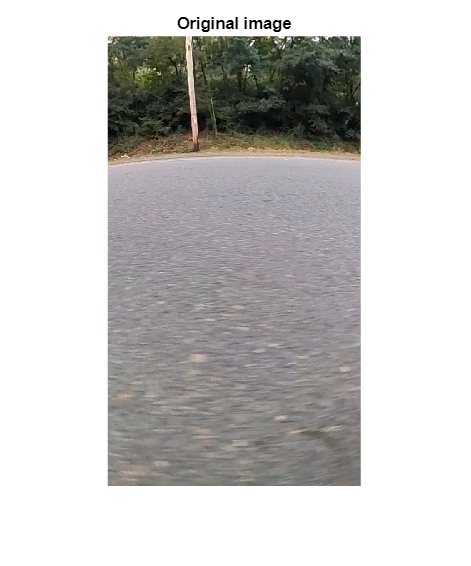

figure, imshow(read(dsTrainGood)), title('Original image')

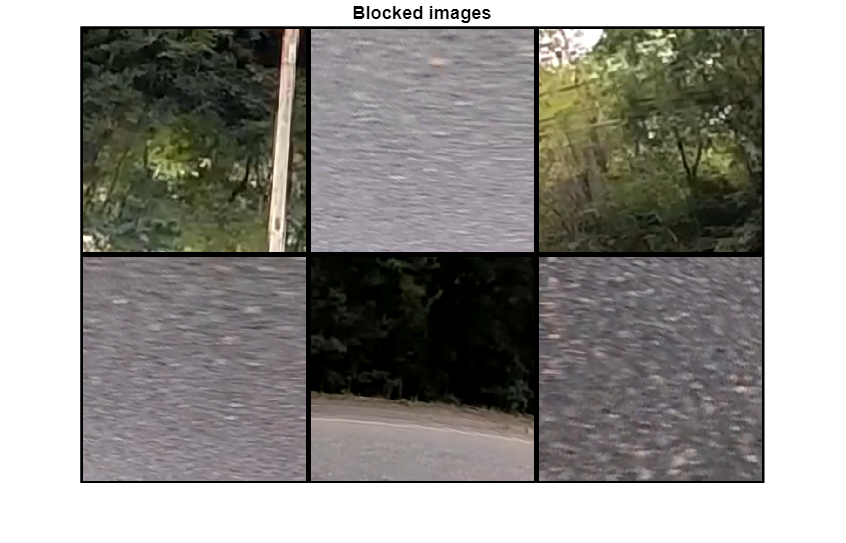

figure, montage(readall(subset(bimdsGood,1:6)), BorderSize=[5 5]), title('Blocked images')

#### Initialize crack image datastore

Similar to above workflow for 'good' images, create a datastore for 'anomaly' images. 

% Split 'anomaly' class files into training, calibration, and testing
[dsTrainAnomalyIm, dsTrainAnomalyMasks, dsCalAnomalyIm, dsCalAnomalyMasks, ...
    dsTestAnomalyIm, dsTestAnomalyMasks] = ...
    util.createAndSplitDatastoresAnomaly(crackDir, 0.4, 0.4);

% create blocked image datastores for 'anomaly' images
bimdsAnomaly = util.createBlockDatastoreAnomaly(dsTrainAnomalyIm.Files, ...
    dsTrainAnomalyMasks.Files, imageSize);

% apply augmentation (rotation, XY-reflection) to 'anomaly' data
bimdsAnomaly = transform(bimdsAnomaly, @augmentBadData);

Similar to the good data, inspect original as well as blocked images of 'anomaly' data 

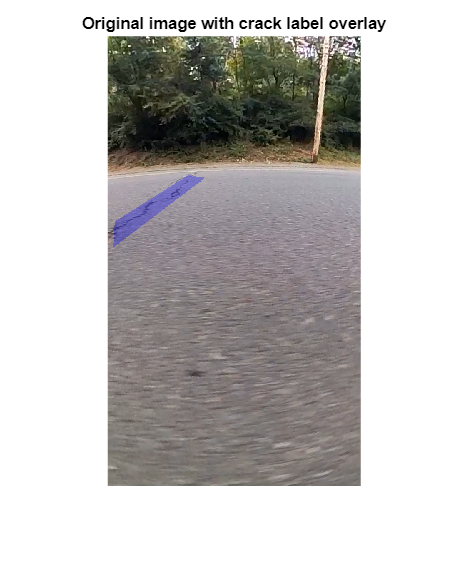

figure;
imshow(labeloverlay(preview(dsTrainAnomalyIm),preview(dsTrainAnomalyMasks),Transparency=0.7));
title('Original image with crack label overlay');

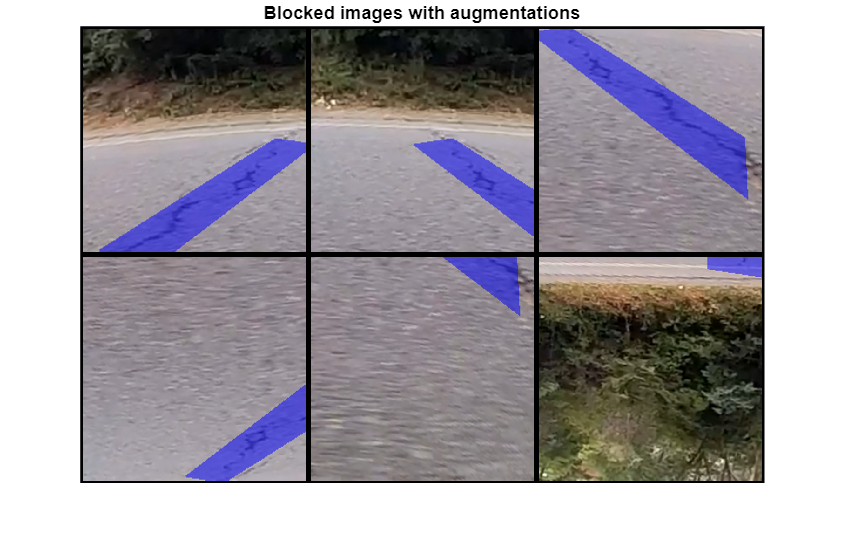


figure;
X = readall(subset(bimdsAnomaly,1:6));
X = arrayfun(@(x) labeloverlay(X{x,1}, X{x,2}), 1:6, 'UniformOutput', false);
montage(X, BorderSize=[5 5]); title('Blocked images with augmentations');

### Part 2: Train Anomaly Detector

#### Initialize detector and training options

The fully convolutional data description (FCDD) network returns a heatmap with the probability that each pixel is anomalous. The classifier labels images as normal or anomalous based on the mean value of the anomaly score heatmap. 

Form an FCDD anomaly detector with a 'googlenet' backbone. 

if doTraining
detector = util.anomalyDetector(imageSize, Backbone="googlenet", DetectorType="fcdd");

Initialize training options

options = trainingOptions('adam', ...
    'InitialLearnRate',1e-4,...
    "BatchNormalizationStatistics","moving",...
    "Shuffle",'every-epoch',...
    "MaxEpochs",30,...
    "MiniBatchSize",8,...
    "Plots","training-progress");

#### Train anomaly detector

Computing Input Normalization Statistics.
 
    Epoch    Iteration    TimeElapsed    LearnRate    TrainingFcddLoss
    _____    _________    ___________    _________    ________________
      1         50         00:00:09       0.0001          0.96228     
      2         100        00:00:25       0.0001          0.94059     
      2         150        00:00:39       0.0001           1.0039     
      3         200        00:00:54       0.0001          0.92174     
      3         250        00:01:09       0.0001           0.3673     
      4         300        00:01:25       0.0001          0.52128     
      4         350        00:01:41       0.0001          0.47067     
      5         400        00:01:59       0.0001          0.60543     
      6         450        00:02:15       0.0001          0.69368     
     

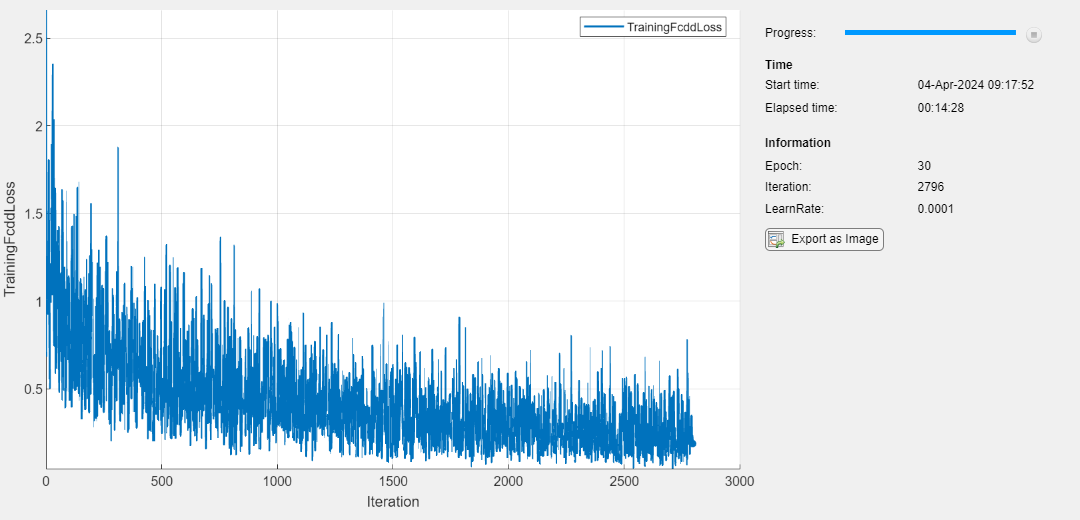

detector = trainFCDDAnomalyDetector(bimdsGood,bimdsAnomaly,detector,options,UseMaskData=true);

else
    detectorObj = load("crackDetector_Pass2.mat");
end

### Part 3: Calibration of Anomaly Detector

Run anomaly detector through calibration dataset. This gives us three main outputs: 

- anomalyThreshold - 

[anomalyThreshold, calAnomalyScores, calGoodScores, minMap, maxMap] = ...
    util.calibrateAnomalyDetector(detector, dsCalGood, dsCalAnomalyIm);

% anomalyThreshold = 0.21;
detector.Threshold = anomalyThreshold;

Plot scores of anomaly images as well as good images to visualize differences.

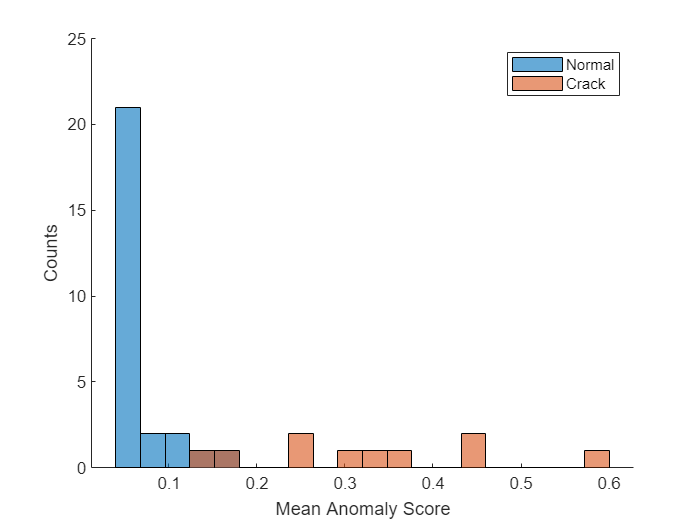

numBins = 20;
[~,edges] = histcounts([calGoodScores, calAnomalyScores],numBins);
figure
hold on
hNormal = histogram(calGoodScores,edges);
hAnomaly = histogram(calAnomalyScores,edges);
hold off
legend([hNormal,hAnomaly],"Normal","Crack")
xlabel("Mean Anomaly Score")
ylabel("Counts")

Save out the detector to a MAT file

if doTraining
    save("crackDetector_"+string(datetime("now", Format="MMddyyyy_HHmm"))+".mat", "detector");
end

### Part 4: Evaluate Anomaly Detector on Unseen Data

#### Run anomaly detector through test data

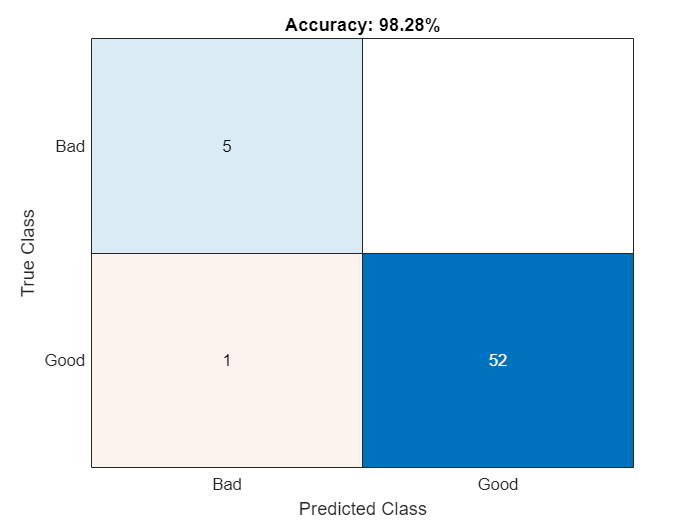

% create a test datastore by combining 'good' and 'anomaly' images
testDs = imageDatastore([dsTestGood.Files; dsTestAnomalyIm.Files]);

% run test dataset through anomaly detector
predLabels = classify(detector, testDs, MiniBatchSize=1);

% compare predicted labels against true labels
trueLabels = [false(1, dsTestGood.numpartitions), true(1, dsTestAnomalyIm.numpartitions)];
M = confusionmat(trueLabels, predLabels);

figure;
cm = confusionchart(M,  ["Good", "Bad"]);
title(sprintf("Accuracy: %.2f%%", nnz(trueLabels==predLabels)/length(trueLabels)*100));

#### Examine true positives

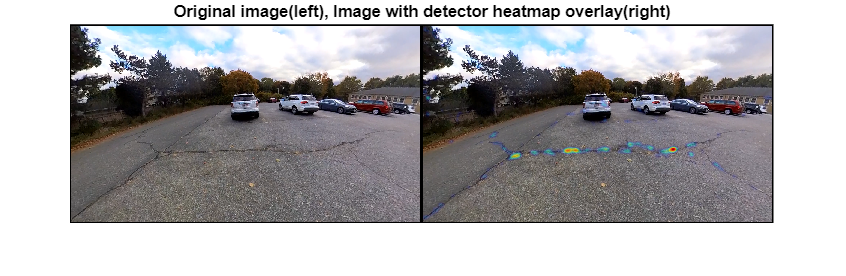

truePositiveIdx = trueLabels & predLabels;
tpDs = subset(testDs, find(truePositiveIdx));
util.displayNextExample(detector, tpDs, minMap, maxMap);

#### Examine true negatives

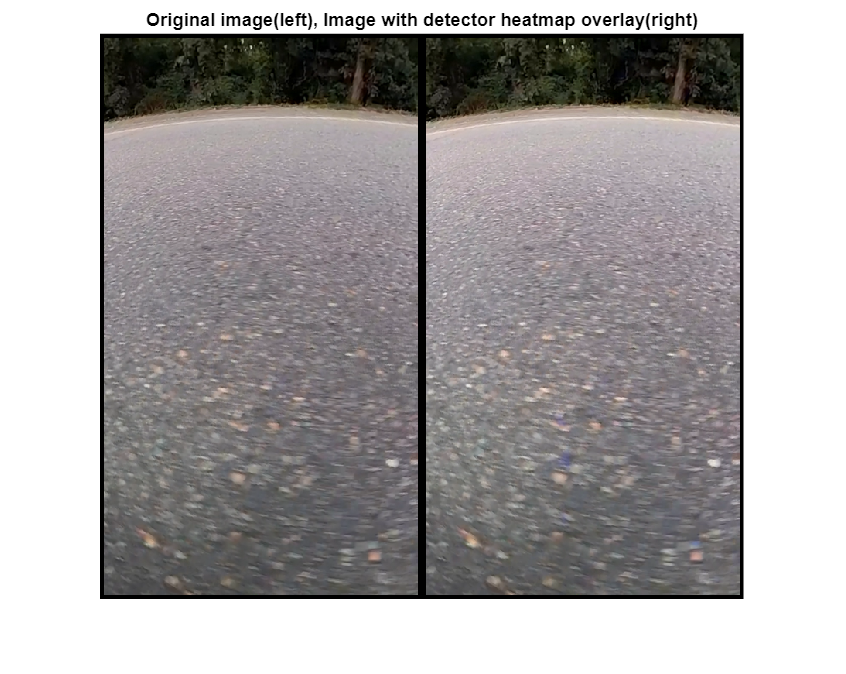

trueNegativeIdx = ~trueLabels & ~predLabels;
tnDs = subset(testDs, find(trueNegativeIdx));
util.displayNextExample(detector, tnDs, minMap, maxMap);

#### Examine false negatives

falseNegativeIdx = trueLabels & ~predLabels;
fnDs = subset(testDs, find(falseNegativeIdx));
util.displayNextExample(detector, fnDs, minMap, maxMap);

No more images to show.


#### Examine false positives

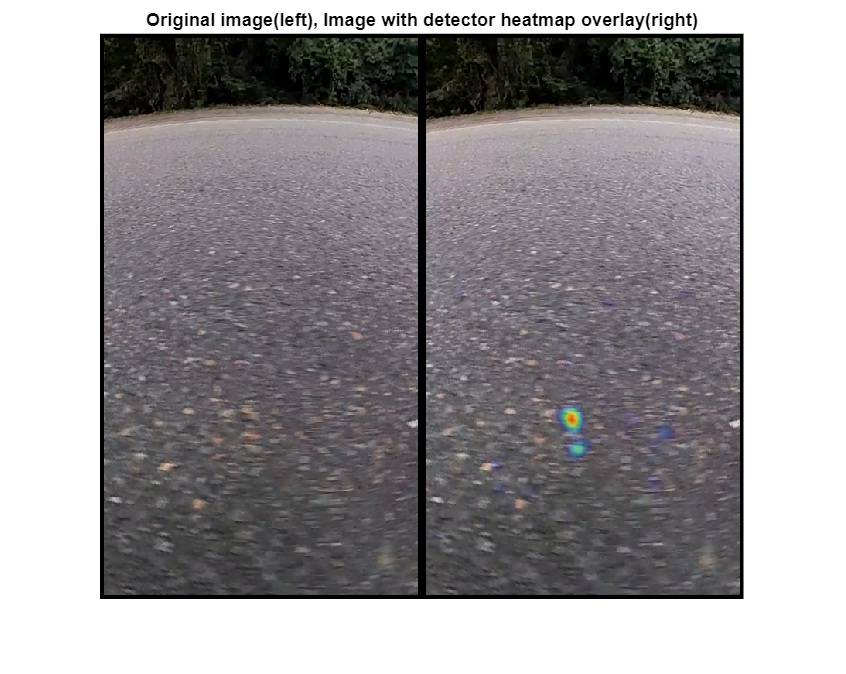

falsePositiveIdx = ~trueLabels & predLabels;
fpDs = subset(testDs, find(falsePositiveIdx));
util.displayNextExample(detector, fpDs, minMap, maxMap);

### Supporting functions

function x = augmentBadData(x)
if rand > 0.5
    x{1} = fliplr(x{1});
    x{2} = fliplr(x{2});
end

if rand > 0.5
    x{1} = flipud(x{1});
    x{2} = flipud(x{2});

end

if rand > 0.5
    x{1} = rot90(x{1},2);
    x{2} = rot90(x{2},2);
end

end

function x = augmentData(x)
    x = x{1};
    if rand > 0.5
        x = fliplr(x);
    end

    if rand > 0.5
        x = flipud(x);
    end

    if rand > 0.5
        x = rot90(x,2);
    end
    x = {x};
end